# Setup

    %r bins and area bins
    maxR = 6400;
    dr = 400;
    r=2.^(0:0.5:log2(maxR/dr))*dr; % log2 scale
    rareas = zeros(1, size(r, 2));
    rareas(1) = 2*pi*r(1)^2;
    rareas(2:end) = 2*pi*(r(2:end).^2-r(1:end-1).^2);

rareas

rareas = 1.0e+08 *

    0.0101    0.0101    0.0201    0.0402    0.0804    0.1608    0.3217    0.6434    1.2868


clear
% Información del archivo .h5
path = "..\\hdf5\A_RS_140819\LFP.h5";
filename = strrep(path, '\', '\\');
dataset = '/LFP';
info = h5info(filename, dataset);
num_times = info.Dataspace.Size(1);

signal = h5read(filename, dataset, [1 1], [num_times 1024]);

load('..\\A_electrode_positions.mat', 'positions_arr')
positions_arr

positions_arr = 1024×2 single matrix
        1400        1400
        1000        1400
         600        1400
         200        1400
        -200        1400
        -600        1400
       -1000        1400
       -1400        1400
        1400        1000
        1000        1000


# Z-score

z_score = (signal- mean(signal, 2))./std(signal, 1, 2);
size(z_score)

ans =      1013080        1024


# 1

Acá calculo la el g(r) para un dado umbral y 3 tiempos distintos. Grafico los electrodos activos y g(r).

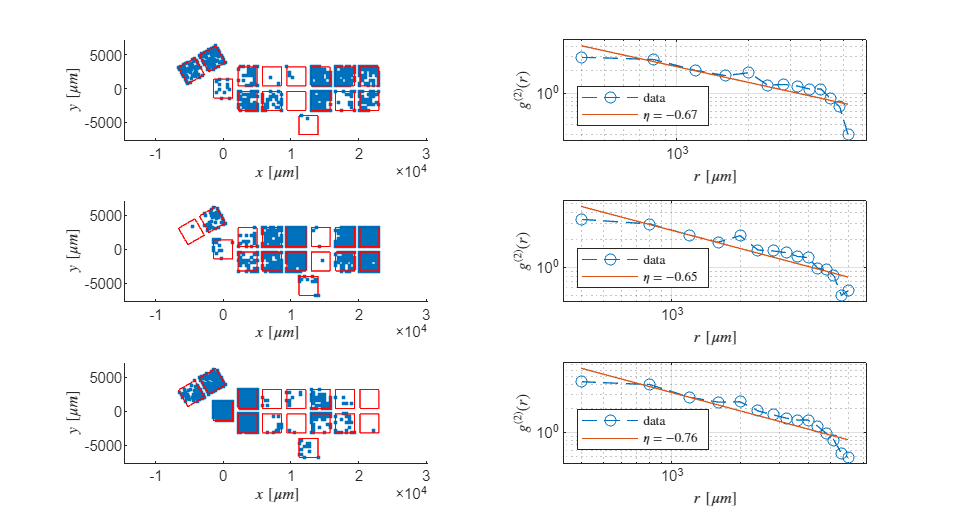

thresh = 0.1;
active_electrodes = z_score>thresh; %
clear figure
figure('units','normalized','outerposition',[0 0 1 1])
target = tiledlayout(3,2);

corners = corners_of_arrays(positions_arr);
dr = 400;

for t=1:2e3:6e3
    X = positions_arr(active_electrodes(t, :), :); % posiciones de electrodos activos
    nexttile;
    scatter(X(:,1), X(:,2), '.');

    hold on
    for arr=1:16
        plot(corners(arr,:,1), corners(arr,:,2), 'r'); % aca ploteo los bordes de los arrays
        hold on
    end
    axis padded equal
    xlabel("$x\; [\mu m]$", "Interpreter", "latex");
    ylabel("$y\; [\mu m]$", "Interpreter", "latex");
    hold off

    nexttile;
    [corrfun, r, rw] = twopointcorr(X(:, 1),X(:, 2), dr); % 2 pt corr para ese dado threshold
    loglog(r, corrfun, '--o');
    
    p = polyfit(log10(r(corrfun>0)), log10(corrfun(corrfun>0)), 1); % ajuste para sacar exponente eta
    x1 = min(r); x2 = max(r); y1 = polyval(p, log10(x1)); y2 = polyval(p, log10(x2));
    hold on
    loglog([x1 x2], 10.^([y1 y2]));

    eta = p(1);
    legend(["data" sprintf("$\\eta=%.2f$", eta)], Interpreter="latex", Location="southwest");

    grid on
    %axis([4e2 7e3 8e-2 6e0])
    axis padded
    xlabel("$r\; [\mu m]$", "Interpreter", "latex");
    ylabel("$g^{(2)}(r)$", "Interpreter", "latex");
end

im_file = sprintf("figuras\\active_electr_threshold%d_twopointcorr.png", thresh*100);
exportgraphics(target, im_file);

# 2

#### 2.1

Calculo el promedio temporal de g(r) y el exponente eta

thresh = 3;
active_electrodes = z_score>thresh; %
dr = 400;

sample_t = 1:1e2:1e5;
times = length(sample_t);

[corrfun_total, r_total, ~] = twopointcorr(positions_arr(:, 1),positions_arr(:, 2), dr);
corrfun = zeros(times, length(r_total));

for i=1:times
    t=sample_t(i);
    active_electrodes_instant = active_electrodes(t, :);
    if sum(active_electrodes_instant) > 2
        X = positions_arr(active_electrodes_instant, :); % posiciones de electrodos activos
        [corrfun_instant, ~, ~] = twopointcorr(X(:, 1),X(:, 2), dr); % two-point-orr para ese dado threshold
        corrfun(i, 1:length(corrfun_instant)) = corrfun_instant;
    end
end

mean_corrfun = mean(corrfun, 1);
std_corrfun = std(corrfun, 1, 1);

p = polyfit(log10(r_total(mean_corrfun>0)), log10(mean_corrfun(mean_corrfun>0)), 1); % ajuste para sacar exponente eta
x1 = min(r_total); x2 = max(r_total); y1 = polyval(p, log10(x1)); y2 = polyval(p, log10(x2));
eta = p(1);


#### 2.2

Grafico los resultados del panel anterior

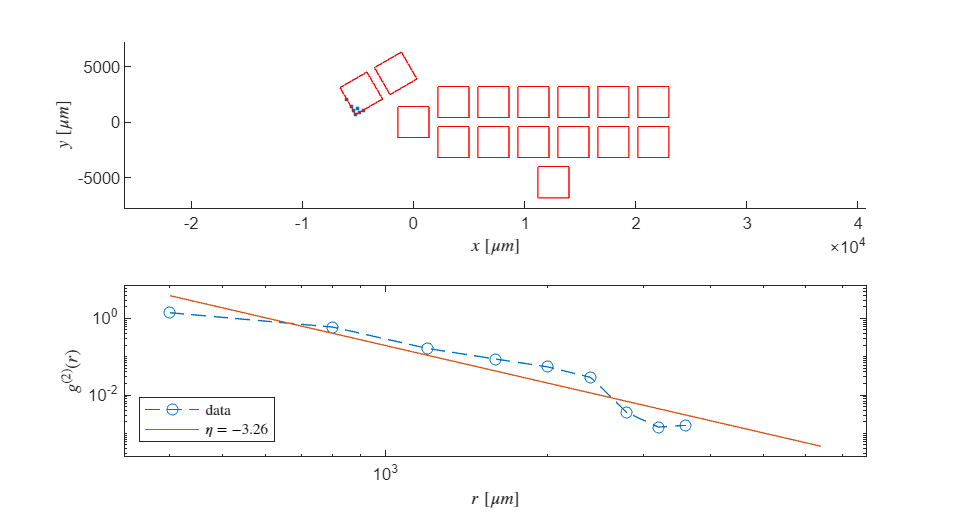

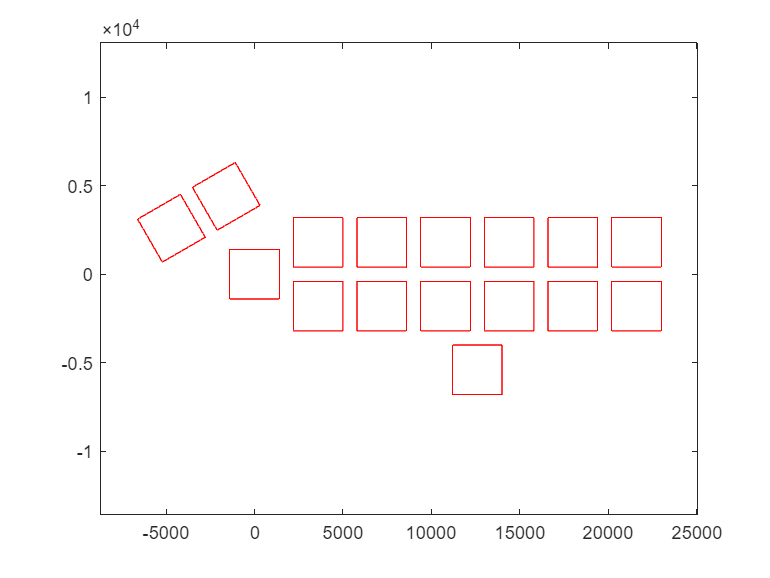

%%%%%%%%%%%% Figure %%%%%%%%%%%%%%%%%
target = tiledlayout(2,1);

%%% Example positions subplot %%%
nexttile;
scatter(X(:,1), X(:,2), '.');
hold on
corners = corners_of_arrays(positions_arr);
for arr=1:16
    plot(corners(arr,:,1), corners(arr,:,2), 'r'); % aca ploteo los bordes de los arrays
    hold on
end
axis padded equal
xlabel("$x\; [\mu m]$", "Interpreter", "latex");
ylabel("$y\; [\mu m]$", "Interpreter", "latex");
hold off

%%% Mean corrfun plot %%%
nexttile;
loglog( r_total(mean_corrfun~=0) , mean_corrfun(mean_corrfun~=0), '--o');
hold on
loglog([x1 x2], 10.^([y1 y2]));

legend(["data" sprintf("$\\eta=%.2f$", eta)], Interpreter="latex", Location="southwest");
axis padded
xlabel("$r\; [\mu m]$", "Interpreter", "latex");
ylabel("$g^{(2)}(r)$", "Interpreter", "latex");


im_file = sprintf("figuras\\twopointcorr_threshold%d.png", thresh*100);
exportgraphics(target, im_file);

# 3

Calculo los exponentes eta y la media de electrodos para distintos umbrales. Grafico dichos resultados

thresholds = 0:0.05:1;
sample_times = 1:1e3:1e5;
dr = 400;
[corrfun_total, r_total, ~] = twopointcorr(positions_arr(:,1), positions_arr(:,2), dr);

[corrfuns, activities] = corrfuns_activities(z_score, positions_arr, thresholds, sample_times, dr, r_total);

Threshold 0.000000
Threshold 0.050000
Threshold 0.100000
Threshold 0.150000
Threshold 0.200000
Threshold 0.250000
Threshold 0.300000
Threshold 0.350000
Threshold 0.400000
Threshold 0.450000
Threshold 0.500000
Threshold 0.550000
Threshold 0.600000
Threshold 0.650000
Threshold 0.700000
Threshold 0.750000
Threshold 0.800000
Threshold 0.850000
Threshold 0.900000
Threshold 0.950000
Threshold 1.000000


temporal_mean_activity = mean(activities, 1);
temporal_mean_corrfun = squeeze(mean(corrfuns, 1));
disp(size(temporal_mean_corrfun));

    21    16



disp(size(temporal_mean_activity));

     1    21



% calculo los etas para cada threshold
eta = zeros(length(thresholds),1);
for i=1:length(thresholds)
    mask=squeeze(temporal_mean_corrfun(i,:)>0);
    p = polyfit( log10(r_total(mask)), ...
        log10(temporal_mean_corrfun(i, mask)), 1); % ajuste para sacar exponente eta
    eta(i) = p(1);
end

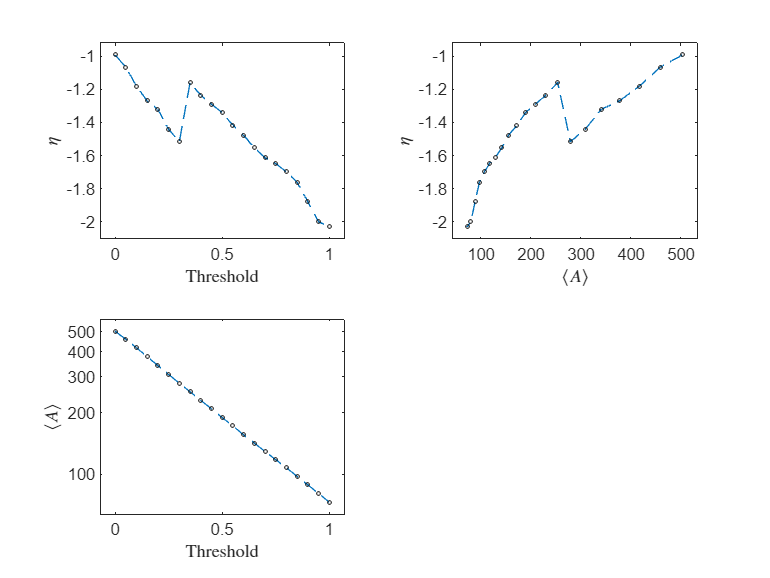

% Plots
target = tiledlayout(2,2);
linestyle = '--o';
mkc = 'black';
mks = 2;

nexttile;
plot(thresholds, eta, linestyle, MarkerEdgeColor=mkc, MarkerSize=mks);
xlabel("Threshold", "Interpreter", "latex")
ylabel("$\eta$", "Interpreter", "latex")
axis padded;

nexttile;
plot(temporal_mean_activity, eta, linestyle, MarkerEdgeColor=mkc, MarkerSize=mks);
xlabel("$\langle A \rangle$", "Interpreter", "latex")
ylabel("$\eta$", "Interpreter", "latex")
axis padded;

nexttile;
semilogy(thresholds, temporal_mean_activity, linestyle, MarkerEdgeColor=mkc, MarkerSize=mks);
xlabel("Threshold", "Interpreter", "latex")
ylabel("$\langle A \rangle$", "Interpreter", "latex")
axis padded;

nexttile;
axis off;

exportgraphics(target, "figuras\\eta_vs_threshold2.png");

target = tiledlayout(1,1);
nexttile;

semilogy(thresholds, temporal_mean_activity, linestyle, MarkerEdgeColor=mkc, MarkerSize=mks);
xlabel("$Threshold$", "Interpreter", "latex")
ylabel("$\langle A \rangle$", "Interpreter", "latex")
axis padded;

exportgraphics(target, "figuras\\activity_vs_threshold.png");

mat = zeros(3,2);
size(mat, 1)

ans = 3

# Funciones

function [corrfuns, activities] = corrfuns_activities(z_score, positions, thresholds, sample_times, dr, r_total)
    % Calculate correlation functions and activities for different
    % times and different thresholds

    % z-score: z_scored signal
    % positions: positions of all the electrodes
    % thresholds: thresholds with which the signal is binarized
    % sample_times: set of times in which corrfun and activity are
    % evaluated
    % dr: distance bin length
    % r_total: distance binning for the whole electrodes positions

    num_times = length(sample_times);
    num_thresh = length(thresholds);
    num_r = length(r_total);

    activities = zeros(num_times, num_thresh);
    corrfuns = zeros(num_times, num_thresh, num_r);

    z_score_sample = z_score(sample_times, :);
    for j=1:num_thresh
        threshold=thresholds(j);
        active_electrodes = z_score_sample > threshold;
        activities(:, j) = sum(active_electrodes, 2);

        fprintf("Threshold %f\n", threshold);
        for i=1:num_times
            %fprintf("Time %f\n", sample_times(i));

            X = positions(active_electrodes(i, :), :); % posiciones de electrodos activos en el instante t
            if size(X,1)>2
                [corrfun, r, ~] = twopointcorr(X(:, 1), X(:, 2), dr);
                corrfuns(i, j, 1:length(r)) = corrfun;
            end
        end
    end
end

function corners = corners_of_arrays(positions)
    corners = zeros(16, 4, 2); % 16 arrays, 4 corners, 2 coordinates
    within_arr_corner_idxs = [1 8 64 57 1];
    for arr=1:16
        for i=1:5
            corner_idx=within_arr_corner_idxs(i);
            corners(arr, i, :) = positions((arr-1)*64+corner_idx,:);
        end
    end
end